# Sistem de filtrare al zgomotului de fundal dintr-o înregistrare vocală - varianta 2

## Înregistrare voce

import dsp.*
 

Fs = 44100;

bufferSize = round(Fs * 0.1);

% Obiect audio device reader
recObj = audioDeviceReader('SampleRate', Fs, 'NumChannels', 1, 'SamplesPerFrame', bufferSize);

% Initializare buffer
audioData = [];

% Inregistrare 10 secunde de audio live
disp('Începe înregistrarea');

Începe înregistrarea


disp('Vorbiți în microfon...');

Vorbiți în microfon...


for i = 1:100  %100*buffer = 10 secunde
    audioData = [audioData; step(recObj)];
end

% Salvam wav inregistrat
filename = 'recorded_audio.wav';
audiowrite(filename, audioData, Fs);

release(recObj);

disp(['Înregistrarea a fost salvată ca: ' filename]);

Înregistrarea a fost salvată ca: recorded_audio.wav


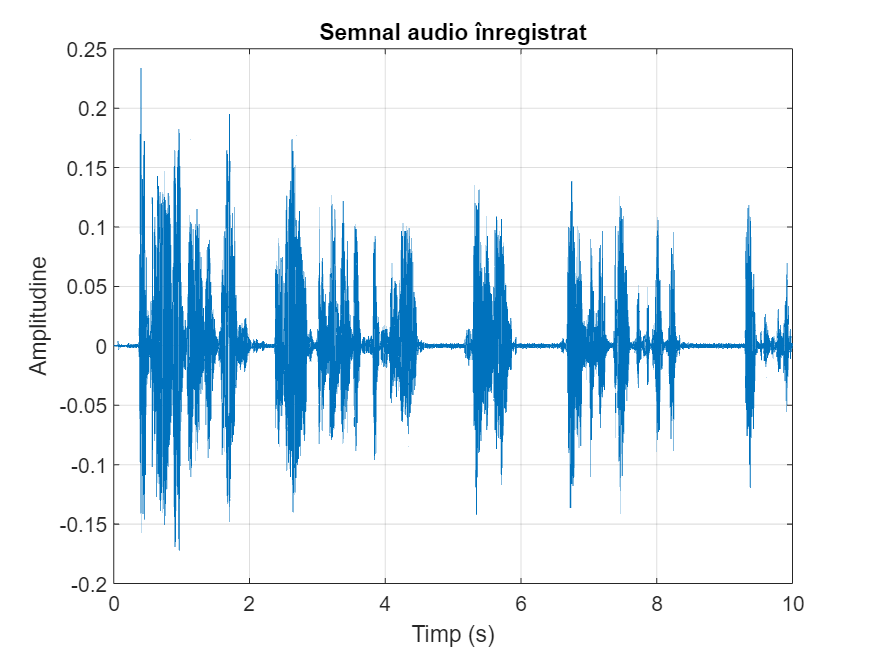


time = (0:length(audioData) - 1) / Fs;
figure;
plot(time, audioData);
xlabel('Timp (s)');
ylabel('Amplitudine');
title('Semnal audio înregistrat');
grid on;

warning('off', 'all');

## Adăugarea unui tip de zgomot pe canal

% Calea catre fisier wav de zgomot
noise_type = "C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\audio\siren";

% Lista tuturor wavurilor din folder
wav_files = dir(fullfile(noise_type, '*.wav'));

% Numarul total de wavuri
num_files = length(wav_files);

% Generare index aleator
rand_index = randi(num_files);

% Alegere fisier aleator de zgomot
filename_zgomot = fullfile(noise_type, wav_files(rand_index).name);

% Display the name of the randomly selected .wav file
 disp(['Fișier selectat: ', filename_zgomot]);

    "Fișier selectat: "    "C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\audio\siren\93567-8-0-19.wav"



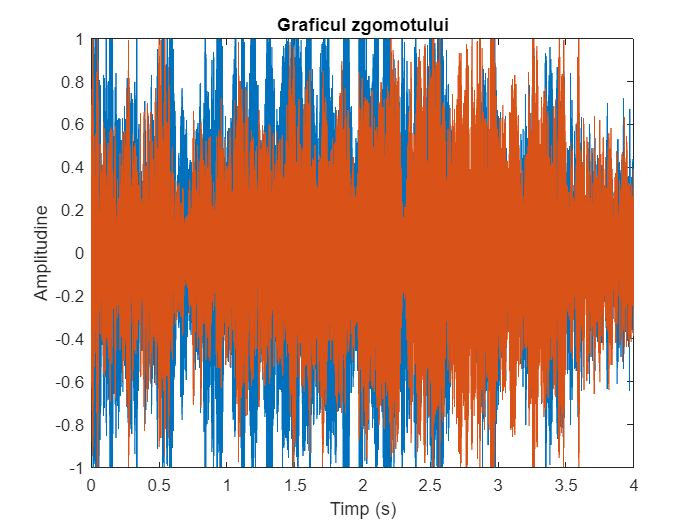


% Creare tabel cu nume inregistrare si nume zgomot
T = table({filename_zgomot}, {filename}, 'VariableNames', {'filename_zgomot', 'filename'});

% Scrie tabelul ca CSV
writetable(T, 'filenames_v2.csv');

[y, Fs] = audioread(filename_zgomot);

t = (0:length(y)-1)/Fs;

figure;
plot(t, y);
title('Graficul zgomotului');
xlabel('Timp (s)');
ylabel('Amplitudine');

## Suprapunere voce + zgomot

 

python_script = 'Overlap2.py';

% % Crearea stringului de comanda
command_str = ['python ', python_script];

% Executa scriptul de comanda
[status, commandOut] = system(command_str);

if status==0
    disp('Cele 2 fișiere WAV au fost suprapuse.')
    disp(commandOut)
else
    disp('Python script did not run successfully.')
    disp('Error:')
    disp(commandOut)
end

Cele 2 fișiere WAV au fost suprapuse.


Fisierul de zgomot extins a fost salvat la: 'C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\noise_extended.wav'.
Fisierul 'C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\audio\siren\93567-8-0-19.wav' si 'recorded_audio.wav' au fost suprapuse in 'C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\mix.wav'.



## Clasificarea zgomotului

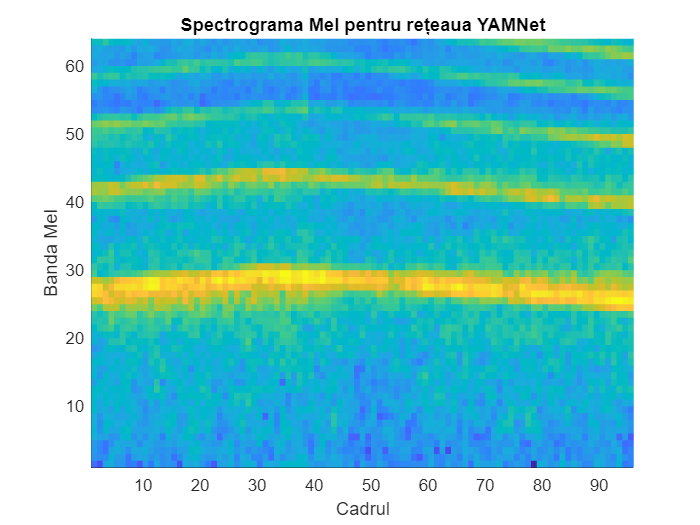

% Calea catre ponderile salvate pentru reteaua neurala
netFilePath = "C:\Users\Mihai\Desktop\FINAL_LICENTA_TOT\LICENTA2\mix.mat";    

[audioIn, fs] = audioread('mix.wav');

spectrograms = yamnetPreprocess(audioIn,fs);

arbitrarySpect = spectrograms(:,:,1,randi(size(spectrograms,4)));
surf(arbitrarySpect,EdgeColor="none")
view([90 -90])
xlabel("Banda Mel")
ylabel("Cadrul")
title("Spectrograma Mel pentru rețeaua YAMNet")
axis tight


% Incarca ponderile in sistem
loadedData = load(netFilePath);

net = loadedData.mix;

tic;
[YPred,probs] = classify(net, spectrograms);
timp_inferenta=toc;

% Afiseaza predictia cu cel mai mare scor

fprintf('Clasa de sunet: %s\n', YPred(1));

Clasa de sunet: siren


fprintf('Timp inferență: %.4f seconds\n', timp_inferenta);

Timp inferență: 0.6344 seconds


## Filtrare / VAD

Puterea zgomotului de fundal înainte de atenuare: -11.3485 dB


Puterea zgomotului de fundal după atenuare: -17.3485 dB


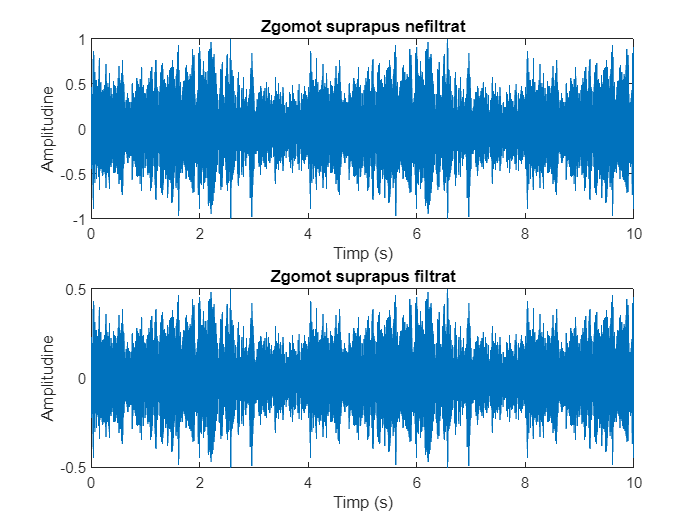

 

% Numele fișierelor de intrare
recordedFile = 'mix.wav';
filename_zgomot = 'noise_extended.wav';

% Citirea fișierelor audio
[x1, fs1] = audioread('mix.wav');
[x2, fs2] = audioread('noise_extended.wav');

% Verificarea că frecvențele de eșantionare sunt aceleași
if fs1 ~= fs2
    error('Frecvențele de eșantionare ale celor două fișiere sunt diferite.');
end

% Definire parametri comuni
fs = fs1;
order = 4; % Ordinul filtrului

t = (0:length(x1)-1)/fs;

% Aplicarea filtrului pe baza valorii YPred(1)
if strcmp(YPred(1), 'engine_idling_voce') || strcmp(YPred(1), 'jackhammer_voce')
    % Highpass Butterworth pentru componenta de 80 Hz
    cutoff_freq = 80; % Frecvența de tăiere
    Wn = cutoff_freq / (fs / 2);
    [b, a] = butter(order, Wn, 'high');
    
    % Aplicarea filtrului pe semnale
    y1 = filter(b, a, x1);
    y2 = filter(b, a, x2);
    
    plot(t, x1);
    title('Înregistrare vocală cu zgomot suprapus nefiltrată');
    xlabel('Timp (s)');
    ylabel('Amplitudine');

    plot(t, y1);
    title('Înregistrare vocală cu zgomot suprapus filtrată');
    xlabel('Timp (s)');
    ylabel('Amplitudine');

    disp(['Fișierele filtrate au fost salvate ca: ', recordedFile, ' și ', filename_zgomot]);

elseif strcmp(YPred(1), 'siren_voce')
    % Bandstop Butterworth centrat pe 800 Hz
    f0 = 800; % Frecvența centrală a filtrului oprește bandă
    bw = 200; % Lățimea benzii de oprire (în Hz)
    Wn = [(f0 - bw/2)/(fs/2), (f0 + bw/2)/(fs/2)];
    [b, a] = butter(order, Wn, 'stop');
    
    % Aplicarea filtrului pe semnale
    y1 = filter(b, a, x1);
    y2 = filter(b, a, x2);

    plot(t, x1);
    title('Înregistrare vocală cu zgomot suprapus nefiltrată');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
    plot(t, y1);
    title('Înregistrare vocală cu zgomot suprapus filtrată');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
    disp(['Fișierele filtrate au fost salvate ca: ', recordedFile, ' și ', filename_zgomot]);

else
    
    % Atenuare de 6 dB pentru zgomot de fundal
    atenuare = 10^(-6/20);
    
    if size(x1, 2) == 2
        x1 = mean(x1, 2);
    end
    if size(x2, 2) == 2
        x2 = mean(x2, 2);
    end

    % Aplicarea atenuării pe semnalele noastre
    y1 = x1 * atenuare;
    y2 = x2 * atenuare;
    putere_inainte = mean(x1.^2);
    putere_dupa = mean(y1.^2);

    putere_inainte_dB = 10 * log10(putere_inainte);
    putere_dupa_dB = 10 * log10(putere_dupa);

    disp(['Puterea zgomotului de fundal înainte de atenuare: ', num2str(putere_inainte_dB), ' dB']);
    disp(['Puterea zgomotului de fundal după atenuare: ', num2str(putere_dupa_dB), ' dB']);

    figure;
    subplot(2, 1, 1);
    plot(t, x1);
    title('Zgomot suprapus nefiltrat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');

    subplot(2,1,2);
    plot(t, y1);
    title('Zgomot suprapus filtrat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
end


% Suprascrierea fișierelor audio filtrate
audiowrite(recordedFile, y1, fs);
audiowrite(filename_zgomot, y2, fs);




## Filtrarea adaptivă a înregistrării

 
[signal, fs_signal] = audioread('mix.wav');
[noise, fs_noise] = audioread('noise_extended.wav');

% Conversia in mono
if size(signal, 2) == 2
    signal = mean(signal, 2);  
end
if size(noise, 2) == 2
    noise = mean(noise, 2);  
end

% Verificare lungime fisiere audio
minLength = min(length(signal), length(noise));
signal = signal(1:minLength);
noise = noise(1:minLength);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Autocorelatie (nu a fost introdusa in proiect)
acf = xcorr(signal, 'coeff');

% Extract the autocorrelation value at zero lag
Rxx = mean(acf);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Create a dsp.LMSFilter object with a specific step size and filter length
filterLength = 64;
mu = 0.0001; % Step size
lms = dsp.LMSFilter('Length', filterLength, 'StepSize', mu);

if strcmp(YPred(1), 'engine_idling_voce') || strcmp(YPred(1), 'jackhammer_voce') || strcmp(YPred(1), 'siren_voce')

    % SNR inainte de filtrare
    SNR_dB_before = snr(signal, noise);
    disp(['Raport semnal-zgomot înainte de filtrare [dB]: ', num2str(SNR_dB_before)]);
    
    % Filtrarea zgomotului folosind filtrul adaptiv LMS
    [e, y] = lms(noise, signal);
    
    % Semnal de eroare
    audiowrite('zgomot_izolat.wav', e, fs_signal);
    
    % Semnal filtrat
    filtered_signal = signal - e;
    
    audiowrite('audio_filtrat.wav', filtered_signal, fs_signal);
    
    % SNR dupa filtrare
    noise_residual = signal - filtered_signal;
    SNR_dB_after = snr(signal, noise_residual);
    disp(['Raport semnal-zgomot după filtrare [dB]: ', num2str(SNR_dB_after)]);
    
    t = (0:length(signal)-1) / fs_signal;
    
    figure;
    subplot(4,1,1);
    plot(t, signal);
    title('Semnal audio nefiltrat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
    subplot(4,1,2);
    plot(t, e);
    title('Zgomotul extras izolat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');
    
    subplot(4,1,3);
    plot(t, filtered_signal);
    title('Semnal filtrat');
    xlabel('Timp (s)');
    ylabel('Amplitudine');

end